clear
clc

syms lfc df theta

lfc_theta(df,theta) = df/tand(theta)

$$lfc\_theta(df, theta) = \frac{\mathrm{df}}{\tan\left(\frac{\pi \,\theta }{180}\right)}$$

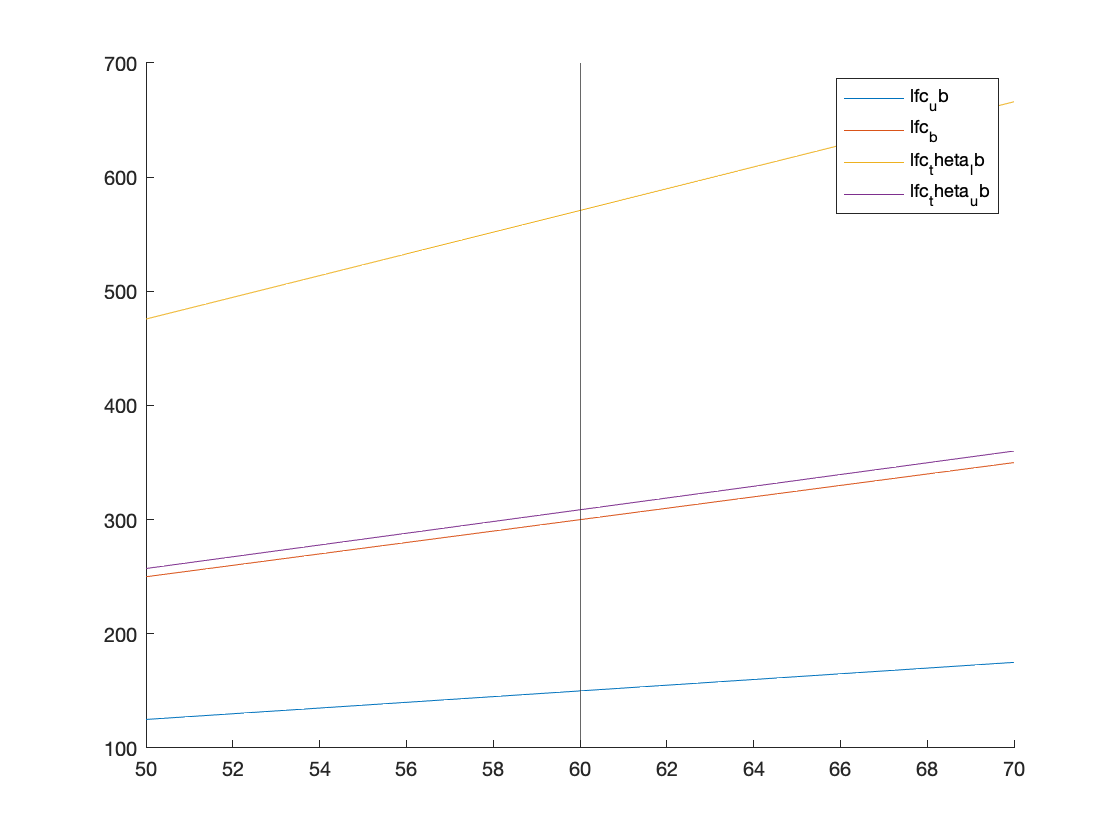


lfc_ub(df) = 2.5*df;
lfc_lb(df) = 5*df;
lf_df = 98.6

figure
hold on
fplot(lfc_ub)
fplot(lfc_lb)
fplot(@(x) lfc_theta(x,6))
fplot(@(x) lfc_theta(x,11))

xline(60)
xlim([50 70])


legend("lfc_ub","lfc_b","lfc_theta_lb","lfc_theta_ub")


double(lfc_theta(60,6))

ans = 570.8619

double(lfc_theta(60,11))

ans = 308.6732